% MatLab(©) Script to generate Bode plots of custom zero/pole location.
%
% Tomas Sadilek @ ControlSystemsAcademy.com
% 2017
%
% Please use appropriate MatLab(? license

clc; clear all; format compact; close all

%poles = [-71 + 71j, -71 + -71j];
poles = [];
zeroes = [1e3];
z = poly(zeroes)

z =            1       -1000


p = poly(poles);
Hs = tf(z,p)

Hs =
 
  s - 1000
 
Continuous-time transfer function.



%x = bodeoptions;
%x.XLim = [0.01 100]

figure(1)
fspace = logspace(0,7,80)

fspace = 	1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0008    0.0010    0.0012    0.0015    0.0018    0.0022


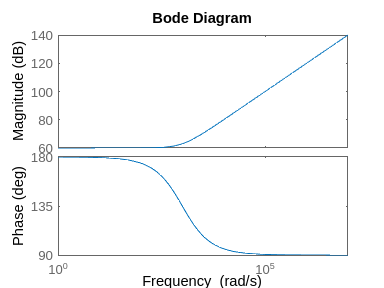

[mag,phase,wout] = bode(Hs,fspace);
bode(Hs,fspace)

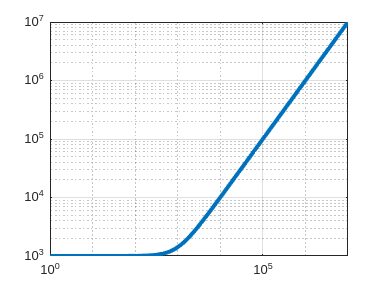

% no more
mag_plot = loglog(fspace,squeeze(mag));
mag_plot(1).LineWidth = 3;
grid on

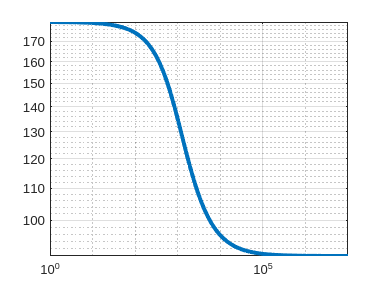

phase_plot = loglog(fspace, squeeze(phase));
phase_plot(1).LineWidth = 3;
grid on

xlim('auto')
ylim('auto')